# Elaborato Fitting di Dati

## Esempio 1-Interpolazione polinomiale di Lagrange

Per il primo esempio si è scelto di mostrare il funzionamento dell'interpolazioni polinomiale di Lagrange. Considerando quindi sei punti esiste un unico polinomio di grado 5 che passa per essi.

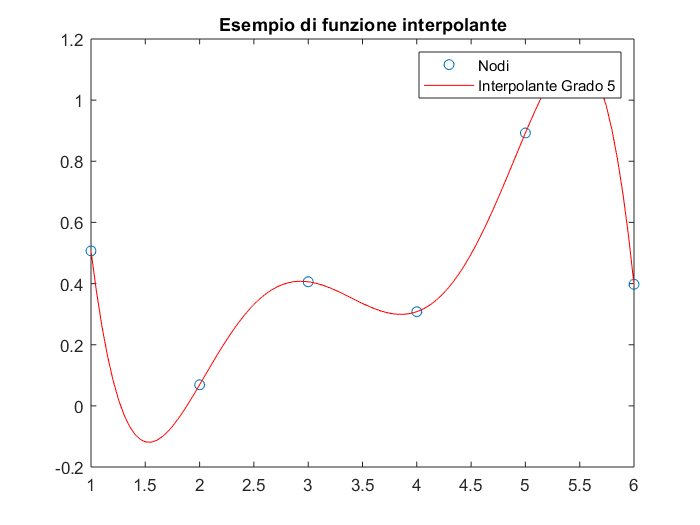

x=1:6;
y=rand(1,6);
figure(1);
nodi=plot(x,y,'o');
hold on;
t=linspace(1,6);
p=polyfit(x,y,5);
f=polyval(p,t);
p1=plot(t,f,'r');
title("Esempio di funzione interpolante");
legend([nodi p1],{'Nodi','Interpolante Grado 5'});

## Esempio 2-Fenomeno di Runge

In questo esempio si mostra il fenomeno di Runge, ossia si cerca di rappresentare la funzione con polinomi di gradi diversi. Contrariamente a quanto si pensi, all'aumentare del grado del polinomio la situazione peggiora e le oscillazioni aumentano notevolmente.

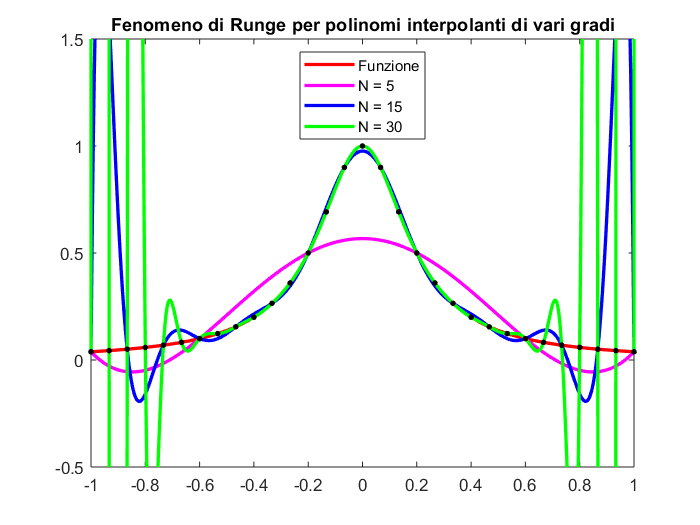

f = @(x) 1./(1 + 25*x.^2);
figure(2);
x = linspace(-1,1,500);
y_true = f(x);
fun=plot(x,y_true,'r','linewidth',2);
hold on;
N = 5; %Grado del polinomio
xdata = linspace(-1,1,N+1);
ydata = f(xdata);
p = polyfit(xdata,ydata,N);
y_fit = polyval(p,x);
poly_5 = plot(x,y_fit,'m','linewidth',2);
plot(xdata,ydata,'k.','markersize',10);

N = 15; %Grado del polinomio
xdata = linspace(-1,1,N+1);
ydata = f(xdata);
p = polyfit(xdata,ydata,N);
y_fit = polyval(p,x);
poly_15 = plot(x,y_fit,'b','linewidth',2);
plot(xdata,ydata,'k.','markersize',10);

N = 30;   %Grado del polinomio
xdata = linspace(-1,1,N+1);
ydata = f(xdata);
p = polyfit(xdata,ydata,N);
y_fit = polyval(p,x);
poly_30 = plot(x,y_fit,'g','linewidth',2);
plot(xdata,ydata,'k.','markersize',10);

axis([-1 1 -0.5 1.5]);
title("Fenomeno di Runge per polinomi interpolanti di vari gradi");
legend([fun,poly_5, poly_15,poly_30],{'Funzione','N = 5','N = 15','N = 30'},'Location','north');

## Esempio 3- Interpolazione a tratti

In questo caso invece mostriamo l'interpolazione a tratti e come all'aumentare del numero di punti considerati ci si avvicini notevolmente alla funzione desiderata.

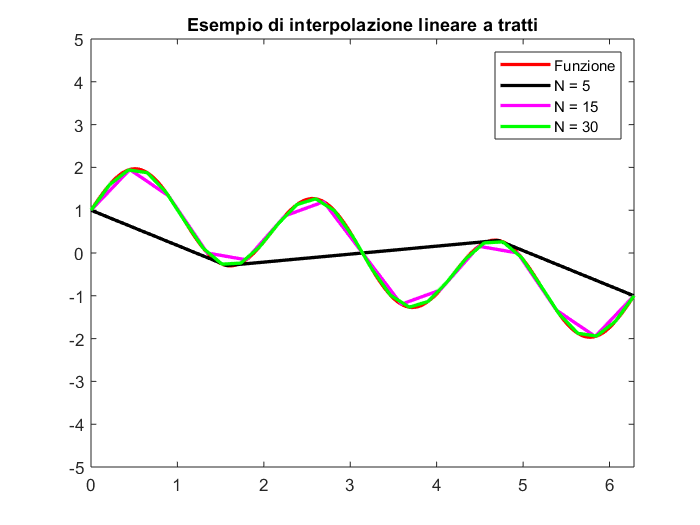

f = @(x) sin(3*x)+cos(x/2);
figure(3);
t = linspace(0,2*pi,500);
y_true = f(t);
fun=plot(t,y_true,'r','linewidth',2);
hold on;
%N=5
x = linspace(0,2*pi,5); 
y = f(x);
pt=interp1(x,y,t);
lin5=plot(t,pt,'k','linewidth',2);
%N=15
x1 = linspace(0,2*pi,15);
y1 = f(x1);
pt1=interp1(x1,y1,t);
lin15=plot(t,pt1,'m','linewidth',2);
%N=30
x2 = linspace(0,2*pi,30);
y2 = f(x2);
pt2=interp1(x2,y2,t);
lin30=plot(t,pt2,'g','linewidth',2);
title("Esempio di interpolazione lineare a tratti");
axis([0 2*pi -5 5]);
legend([fun,lin5, lin15,lin30],{'Funzione','N = 5','N = 15','N = 30'},'Location','northeast');

## Esempio 4-Confronto tra interpolante a tratti lineare e cubica

Si mostra di seguito invece come la spline naturale cubica rispetto all'interpolante a tratti negli estremi degli intervallini sia continua e quindi eviti le discontinuità.

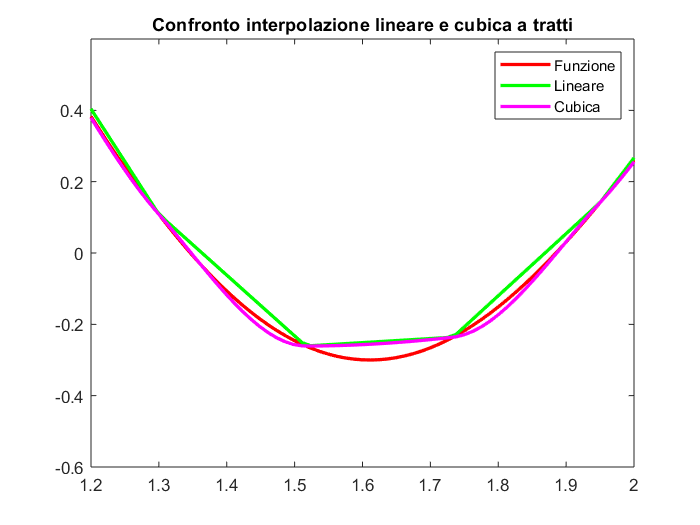

f = @(x) sin(3*x)+cos(x/2);
figure(4);
t = linspace(0,2*pi,500);
y_true = f(t);
fun=plot(t,y_true,'r','linewidth',2);
hold on;
%Lineare
x = linspace(0,2*pi,30);
y = f(x);
pt=interp1(x,y,t);
lin=plot(t,pt,'g','linewidth',2);
%Cubica
ptc=interp1(x,y,t,'pchip'); 
cub=plot(t,ptc,'m','linewidth',2);
title("Confronto interpolazione lineare e cubica a tratti");
axis([1.2 2 -0.6 0.6]);
legend([fun,lin,cub],{'Funzione','Lineare','Cubica'},'Location','northeast');

## Esempio 5- Confronto tra polinomio interpolante e spline naturale cubica

In questo caso invece si mostra come la spline rispetto al polinomio interpolante minimizzi le oscillazioni.

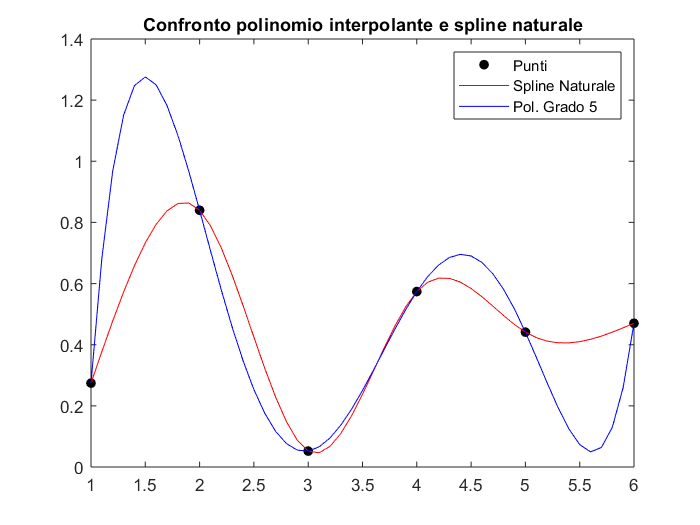

x=1:6;
y=rand(1,6);
figure(5);
punti=plot(x,y,'k.','MarkerSize',20);
hold on;

pp=csape(x,y,'second');%Spline naturale cubica
t=1:.1:6;
ys=ppval(pp,t);
spline=plot(t,ys,'r');

p=polyfit(x,y,5); %Polinomio grado 5
pl=polyval(p,t);
pol=plot(t,pl,'b');
title("Confronto polinomio interpolante e spline naturale");
legend([punti,spline,pol],{'Punti','Spline Naturale','Pol. Grado 5'},'Location','northeast');

## Esempio 6- Spline not a knot e sua derivata

In questo esempio viene utilizzata la rappresentazione polinomiale a tratti della spline cubica not-a-knot per rappresentare la derivata della funzione. Questo esempio mostra un modo in cui poter utilizzare la pp-form.

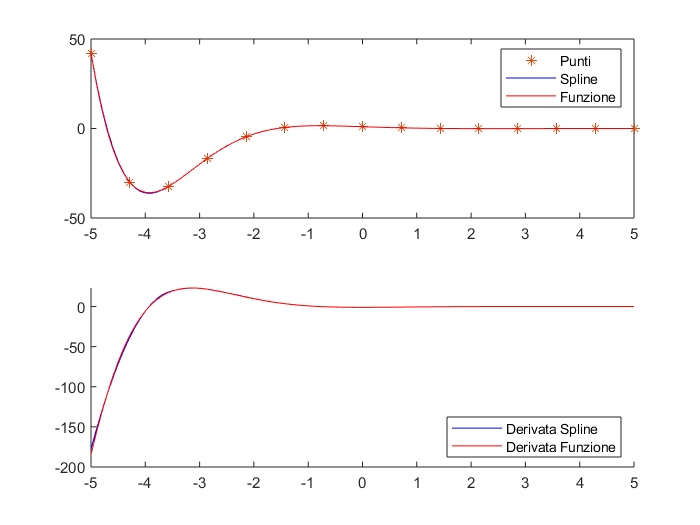

%Definizione spline e derivata
x=linspace(-5,5,15);
xx=linspace(-5,5);
y=exp(-x).*cos(x);
yy=exp(-xx).*cos(xx);
yd=-exp(-xx).*(sin(xx)+cos(xx));
figure(7)
subplot(2,1,1);
punti=plot(x,y,'*');
hold on;
%pp form spline e derivata
pp=spline(x,y);
sder=fnder(pp,1);
%valutazione spline e derivata
sp=ppval(pp,xx);
sd=ppval(sder,xx);
spl=plot(xx,sp,'b');
fun=plot(xx,yy,'r');
legend([punti,spl,fun],{'Punti','Spline','Funzione'},'Location','northeast');
subplot(2,1,2);
hold on;
spld=plot(xx,sd,'b');
fund=plot(xx,yd,'r');
legend([spld,fund],{'Derivata Spline','Derivata Funzione'},'Location','southeast');

## Esempio 7- Confronto spline cubica e not a knot

In questo esempio invece confrontiamo le due tipologie di spline mostrando come la spline naturale minimizzi le oscillazioni tra i nodi.

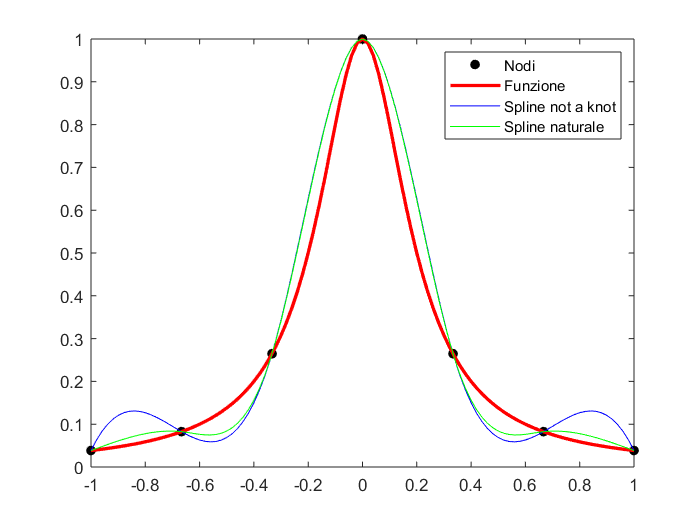

x=linspace(-1,1,7);
xx = linspace(-1,1,101);
y = 1./(1 + 25*x.^2);
yf=1./(1 + 25*xx.^2);
figure(8);
nodi=plot(x,y,'k.','MarkerSize',20);
hold on;
fun=plot(xx,yf,'r','linewidth',2);
%not a knot
cs=spline(x,y,xx);
knot=plot(xx,cs,'b');
%naturale
pp=csape(x,y,'second');
yy=ppval(pp,xx);
spl=plot(xx,yy,'g');
legend([nodi,fun,knot,spl],{'Nodi','Funzione','Spline not a knot','Spline naturale'},'Location','northeast');

## Esempio 8-Interpolazione parametrica

Le equazioni parametriche sono curve impossibili da rappresentare con una sola funzione interpolante. Si utilizza quindi la spline interpolante parametrica mostrandone il funzionamento in alcuni esempi.

Nel primo esempio si vuole interpolare la curva Cubica di Tschirnhausen

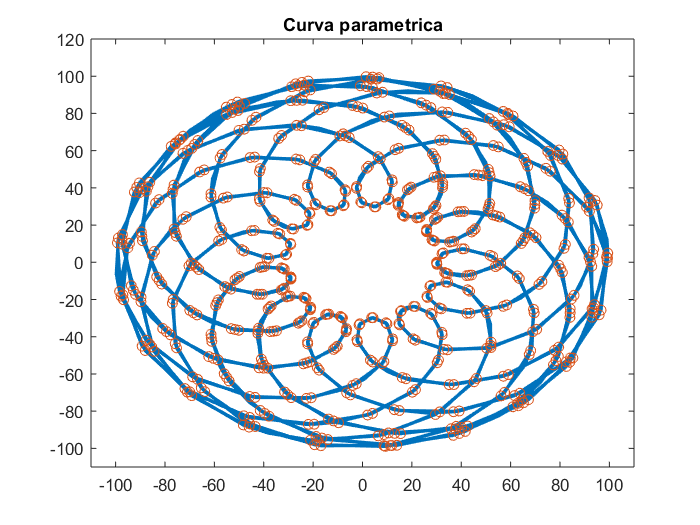

t=linspace(0,300,600);
x=-35*cos(t)+65*cos(-.35*t);
y=-35*sin(t)-65*sin(-.35*t);
points=[x;y];
figure(9)
fnplt(cscvn(points));
hold on;
plot(points(1,:),points(2,:),'o')
title("Curva parametrica");
axis([-110 110 -110 120]);

In questo esempio invece si interpola una curva che non si può ricondurre ad una precisa funzione matematica

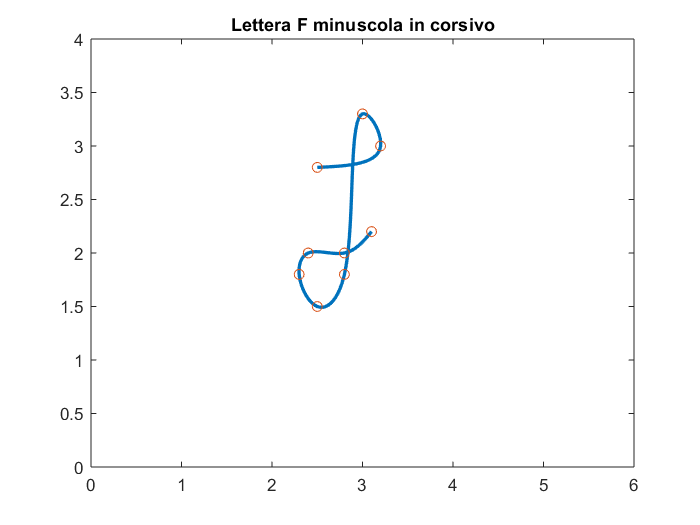

x=[2.5 3.2 3 2.8 2.5 2.3 2.4 2.8 3.1];
y=[2.8 3 3.3 1.8 1.5 1.8 2 2 2.2];
points=[x;y];
figure(10)
fnplt(cscvn(points));
hold on;
plot(points(1,:),points(2,:),'o');
 title("Lettera F minuscola in corsivo");
axis([0 6 0 4]);

In quest'ultimo invece si rappresenta una spirale nello spazio.

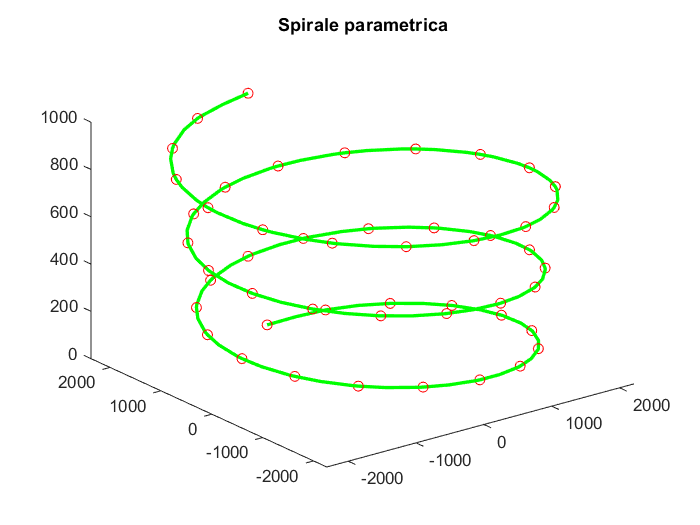

figure(11)
t=linspace(0,6*pi,50);
x1=(t.^2+t+2000).*sin(t);
y1=(t.^2+t+2000).*cos(t);
z1=50.*t;
xyz=[x1;y1;z1];
plot3(xyz(1,:),xyz(2,:),xyz(3,:),'ro');
title("Spirale parametrica");
hold on
fnplt(cscvn(xyz),'g',2);

## Esempio 9- Interpolazione bidimensionale

Qui invece si utilizza l'interpolazione bidimensionale con vari metodi. Mostrando sempre come l'interpolazione con spline produca la curva più liscia.

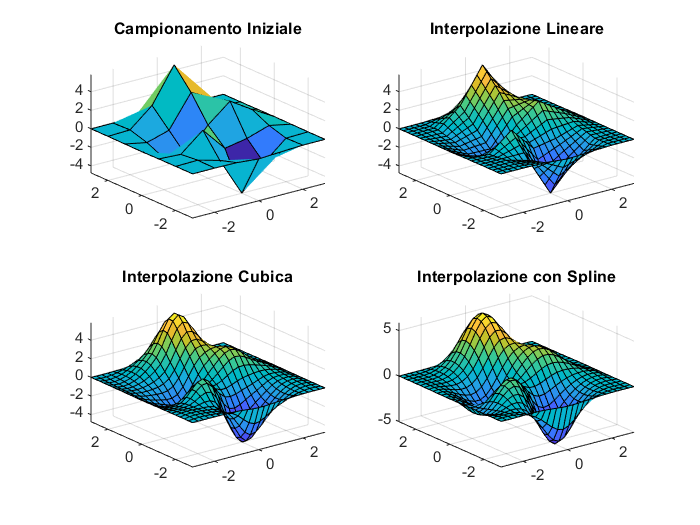

[X,Y] = meshgrid(-3:3);
V = peaks(X,Y);
figure(12)
subplot(2,2,1);
surf(X,Y,V)
title('Campionamento Iniziale');
[Xq,Yq] = meshgrid(-3:0.25:3);
Vq = interp2(X,Y,V,Xq,Yq);
subplot(2,2,2);
surf(Xq,Yq,Vq);
title('Interpolazione Lineare');
Vq = interp2(X,Y,V,Xq,Yq,'cubic');
subplot(2,2,3);
surf(Xq,Yq,Vq);
title('Interpolazione Cubica');
Vq = interp2(X,Y,V,Xq,Yq,'spline');
subplot(2,2,4);
surf(Xq,Yq,Vq);
title('Interpolazione con Spline');

## Esempio 10-Smoothing - Minimi Quadrati Polinomiali

Per lo smoothing invece vogliamo conoscere l'andamento globale di un fenomeno. In questo esempio utilizziamo il metodo dei Minimi Quadrati Polinomiali mostrando come il polinomio di grado 2 rappresenti leggermente meglio l'andamento dei dati.

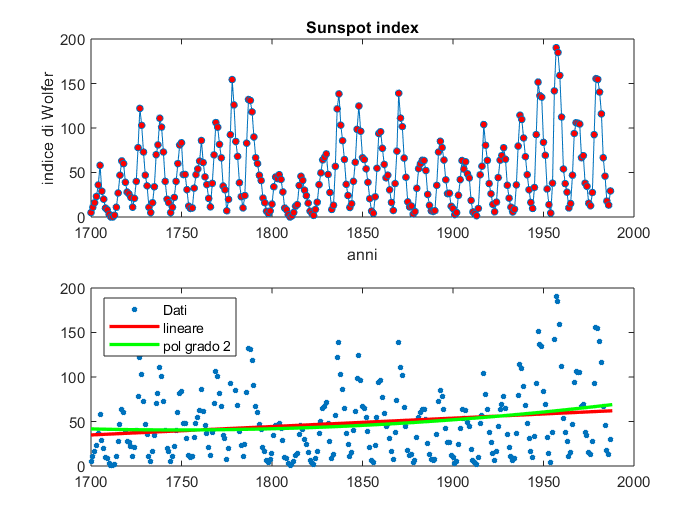

load sunspot.dat
x=sunspot(:,1);
y=sunspot(:,2);
figure(13)
subplot(2,1,1)
plot(x,y,'-o','MarkerFaceColor','r','MarkerSize',4);
title('Sunspot index');
xlabel('anni');
ylabel('indice di Wolfer');

t=linspace(1700,1988);
p=polyfit(x,y,1);
s=polyval(p,t);
pp=polyfit(x,y,2);
ss=polyval(pp,t);
subplot(2,1,2)
title('Smoothing Dati');
plot(x,y,'*',t,s,'r',t,ss,'g','MarkerSize',3,'LineWidth',2);
legend('Dati','lineare','pol grado 2','Location','NorthWest')

## Esempio 11-Smoothing - Spline Smoothing

Per quanto riguarda la spline di smoothing si può vedere che se viene scelto il parametro p direttamente dalla funzione non si ha un andamento regolare, ma scegliendolo opportunamente vediamo come le funzioni generate seguano molto più accuratamente l'andamento del fenomeno.

figure(14)
x=-4*pi:0.1:4*pi;
t=-4*pi:0.005:4*pi;
%viene perturbata la funzione sinc(x)
y=(sin(x)./x)+1/4*randn(1,length(x));
%P scelto di default
[pp, p]=csaps(x,y);
p

p = 0.9999

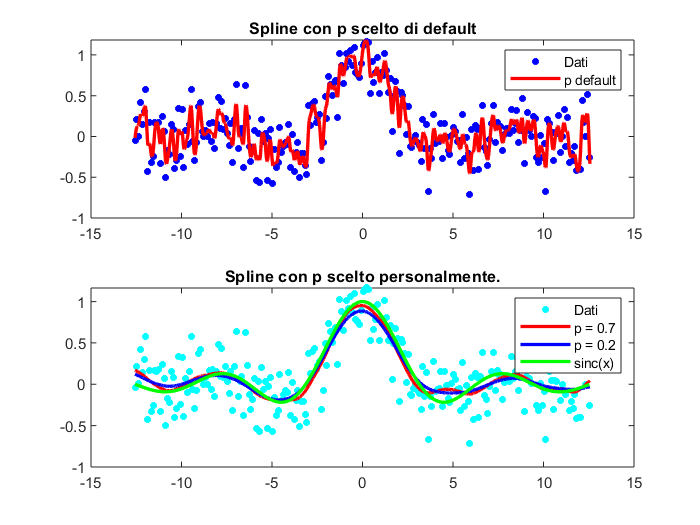

y0=sin(x)./x; %sinc
ys=ppval(pp,t);
subplot(2,1,1)
plot(x,y,'*b',t,ys,'r','LineWidth',2,'MarkerSize',4);
title("Spline con p scelto di default")
legend('Dati', 'p default');
% p scelto personalmente 
pp7=csaps(x,y,.7);
ys1=ppval(pp7,t);
pp2=csaps(x,y,.2);
ys2=ppval(pp2,t);
subplot(2,1,2)
plot(x,y,'*c',t,ys1,'r',t,ys2,'b',x,y0,'g','LineWidth',2,'MarkerSize',4);
title("Spline con p scelto personalmente.")
legend('Dati', 'p = 0.7', 'p = 0.2','sinc(x)');

## Esempio 12- Smoothing - Confronto spline cubica retta e polinomimo

In questo esempio  confrontiamo lo smoothing tramite spline e tramite minimi quadrati polinomiali. In questo caso quindi si vede perfettamente come la spline segua più fedelmente il fenomeno osservato.

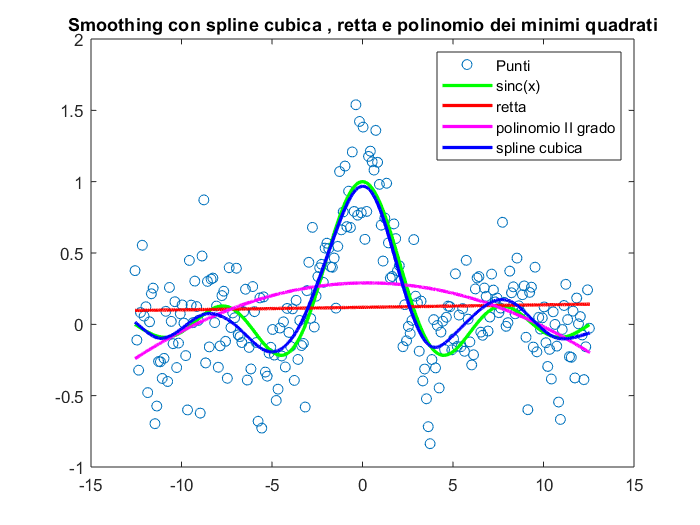

figure(15)
x=-4*pi:0.1:4*pi;
t=-4*pi:0.005:4*pi;
y=(sin(x)./x)+1/4*randn(1,length(x));
plot(x,y,'o')
hold on;
y0=sin(x)./x;
plot(x,y0,'g','LineWidth',2)
p=polyfit(x,y,1);
s=polyval(p,t);
plot(t,s,'r','LineWidth',2)
pp=polyfit(x,y,2);
ss=polyval(pp,t);
plot(t,ss,'m','LineWidth',2)
pp2=csaps(x,y,.2);
ys2=ppval(pp2,t);
plot(t,ys2,'b','LineWidth',2)
title("Smoothing con spline cubica , retta e polinomio dei minimi quadrati")
legend('Punti','sinc(x)','retta','polinomio II grado','spline cubica');

## Esempio 13- Smoothing - Confronto spline cubica retta e polinomimo

In quest'altro esempio invece confrontiamo sempre spline e minimi quadrati polinomiali, ma nel caso osservato è più utile per capire l'andamento del fenomeno utilizzare la seconda tipologia di metodi.

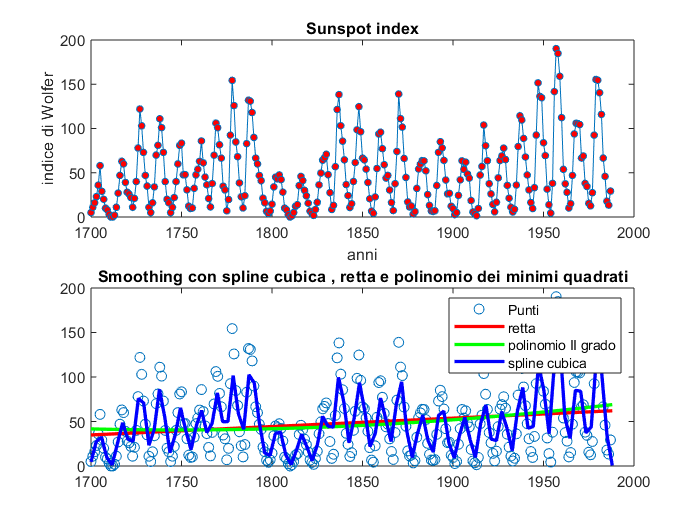

figure(16)
load sunspot.dat
x=sunspot(:,1);
y=sunspot(:,2);
figure(13)
plot(x,y,'o')
hold on;
t=linspace(1700,1988);
p=polyfit(x,y,1);
s=polyval(p,t);
plot(t,s,'r','LineWidth',2)
pp=polyfit(x,y,2);
ss=polyval(pp,t);
plot(t,ss,'g','LineWidth',2)
pp2=csaps(x,y,.2);
ys2=ppval(pp2,t);
plot(t,ys2,'b','LineWidth',2)
title("Smoothing con spline cubica , retta e polinomio dei minimi quadrati")
legend('Punti','retta','polinomio II grado','spline cubica');

## Esempio 14- Smoothing - Spline parametrica

In questo esempio invece le equazioni parametriche sono affette da rumore e reamite la spline parametrica si ricostruisce abbastanza fedelmente il fenomeno osservato.

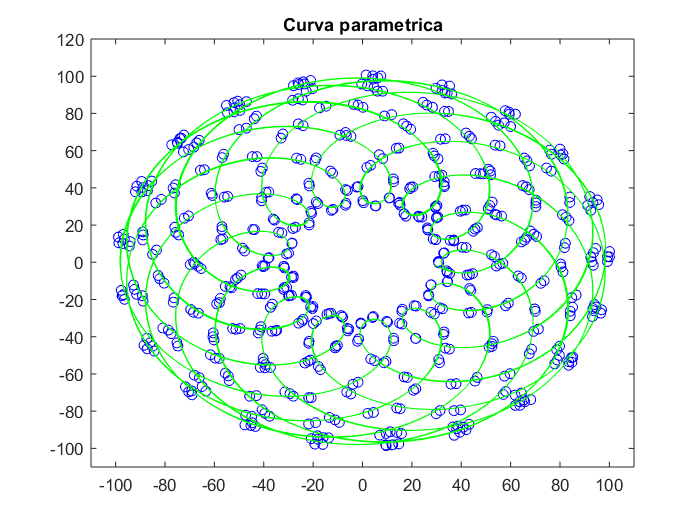

figure(17)
t=linspace(0,300,600);
n=length(t);
x=-35*cos(t)+65*cos(-.35*t)+rand(1,n);
y=-35*sin(t)-65*sin(-.35*t)+rand(1,n);
s=(1:n)';
tt=(1:1/8:n)';
pu=csaps(s,x,.6);
pv=csaps(s,y,.6);
ys=ppval(pu,tt);
yv=ppval(pv,tt);
plot(x,y,'bo',ys,yv,'g-');
title("Curva parametrica");
axis([-110 110 -110 120]);

## Esempio 15 -Smoothing estrapolazione

In questo esempio invece osserviamo una funzione in un intervallo piccolo e vogliamo capirne l'andamento al di fuori. In particolare si osserva che la spline riproduce molto similmente la funzione, mentre il polinomio interpolante è molto distante dalla funzione osservata.

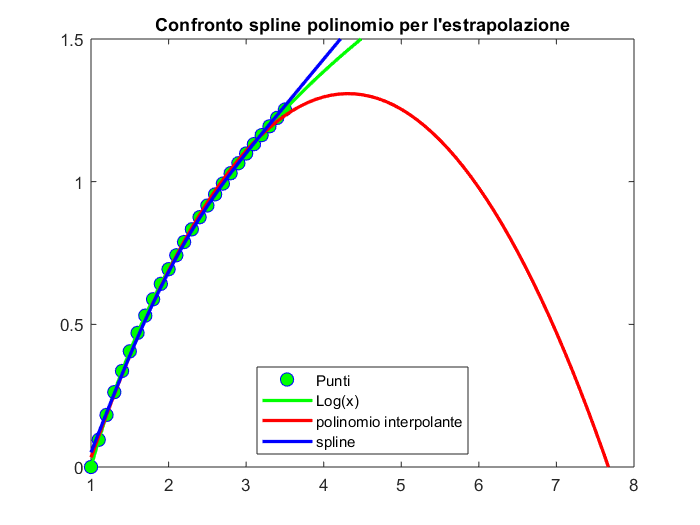

x=(1:.1:3.5);
y=log(x);
figure(18)
plot(x,y,'bo','MarkerFaceColor','g','MarkerSize',8)
hold on
p=polyfit(x,y,2);
pp=fnxtr(csaps(x,y,.85));
x=(1:.1:8);
y=log(x);
f=polyval(p,x);
ys=ppval(pp,x);
plot(x,y,'-g',x,f,'-r',x,ys,'-b','LineWidth',2)
legend('Punti','Log(x)','polinomio interpolante','spline','Location','south')
title("Confronto spline polinomio per l'estrapolazione")
axis([1 8 0 1.5])

## Esempio 16- Smoothing - previsione

In questo esempio si cerca di fare previsioni su dei dati in possesso. In particolare si sono considerati questi dati che rappresentano la media mondiale dei minuti spesi su siti di venditori online su diversi tipi di devices dal 2015 al 2018 per ogni quadrimestre.

x=1:15;
%Dati
tablet=[7 7 7 7 7 7 8 8 7 5 5 5 5 5 5];
smartphone=[6 5 6 6 5 5 6 6 5 4 4 4 4 4 4];
desktop=[6 6 7 7 6 6 7 7 6 5 5 5 5 5 6];

Di questi dati quindi si produce un grafico che ne rappresenta l'andamento osservato.

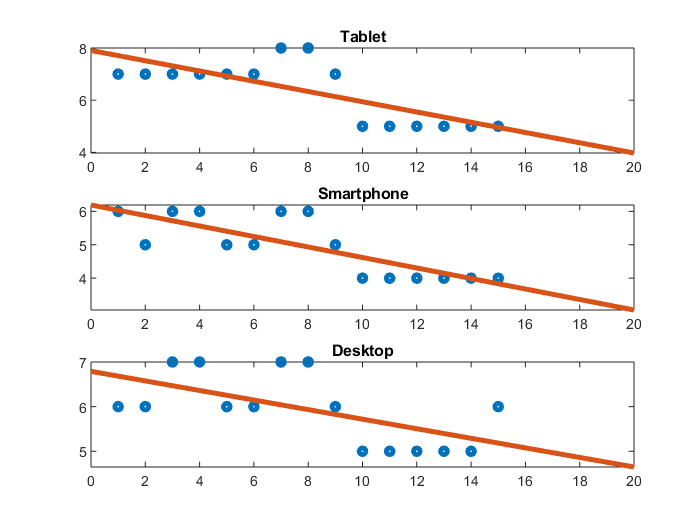

%Andamento negli anni
t=linspace(0,20);
figure(19)
c1=polyfit(x,tablet,1);
v1=polyval(c1,t);
subplot(3,1,1)
plot(x,tablet,'o',t,v1,'LineWidth',3,'MarkerSize',4),title ('Tablet');
c2=polyfit(x,smartphone,1);
v2=polyval(c2,t);
subplot(3,1,2)
plot(x,smartphone,'o',t,v2,'LineWidth',3,'MarkerSize',4),title ('Smartphone');
c3=polyfit(x,desktop,1);
v3=polyval(c3,t);
subplot(3,1,3)
plot(x,desktop,'o',t,v3,'LineWidth',3,'MarkerSize',4),title ('Desktop');

Ora quindi si cerca di prevedere come sarà l'andamento nel 2019 e si confrontano i risultati trmite dei grafici a torta in cui si capisce come l'utilizzo desktop è probabile che aumenti rispetto all'uso dello smartphone.

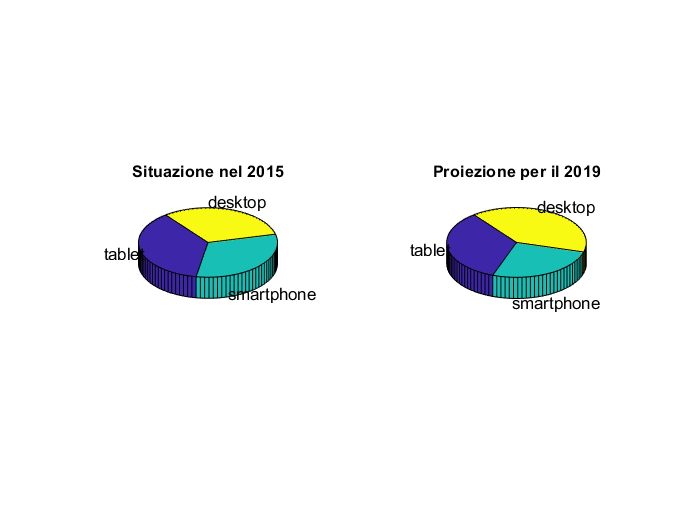

%Previsione 2019
figure(20)
first=[tablet(1),smartphone(1),desktop(1)];
pro=[v1(100),v2(100),v3(100)];
subplot(1,2,1)
pie3(first,{'tablet','smartphone','desktop'}),title('Situazione nel 2015');
subplot(1,2,2)
pie3(pro,{'tablet','smartphone','desktop'}),title('Proiezione per il 2019');

## Esempio 17 - Smoothing superficie

In questo esempio invece si effettua lo smoothing di una superficie dopo che è stata perturbata con del rumore, mostrando come si ricostruisca precisamente la superficie di partenza.

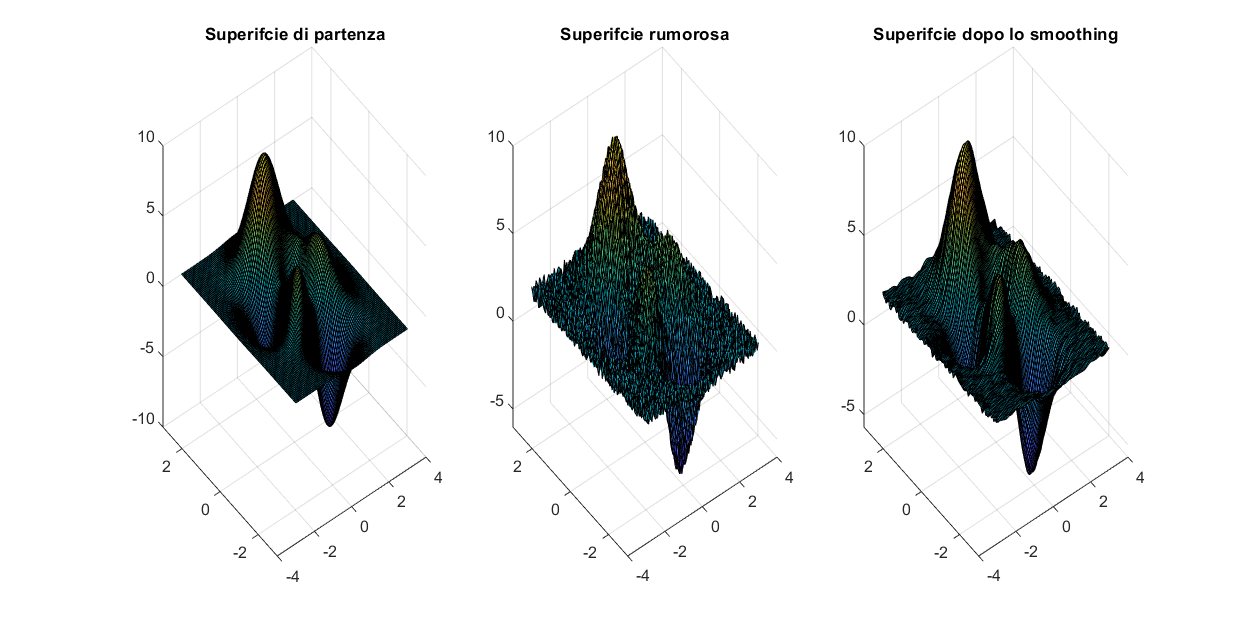

x=linspace(-3,3);
y=linspace(-3,3);
[X,Y] = meshgrid(x,y);
figure(21)
set(gcf, 'Position',  [400, 200, 1000, 500])
V = peaks(X,Y);
subplot(1,3,1)
surf(X,Y,V)
title("Superifcie di partenza");
noisy=V+(rand(size(V))+.5);

subplot(1,3,2)
surf(X,Y,noisy)
title("Superifcie rumorosa");
subplot(1,3,3)
pp=csaps(x,noisy,.996);
smooth=ppval(pp,x);
surf(X,Y,smooth)
title("Superifcie dopo lo smoothing");

## Esempio 18 -Modifica di immagini

In quest'ultimo esempio infine si mostra come si possano migliorare anche le immagini. In particolare si carica un'immagine e la si migliora con varie metodologie.

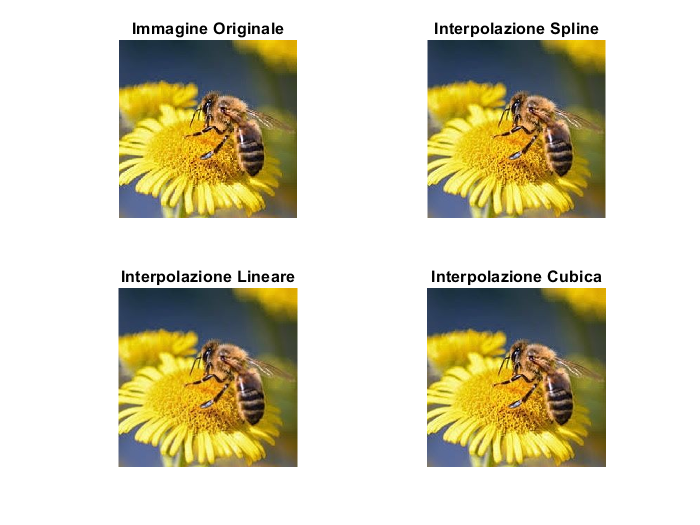

I=imread('ape.jpg');
% Salvataggio dimensioni originali
[r,c,v] = size(I);
% Salvataggio griglia originale
old_x = 1:c; 
old_y = 1:r;
% Creiamo una griglia con dimensioni dieci volte più fitta
new_x = linspace(1,c,2*c)';
new_y = linspace(1,r,2*r);
% Preallochiamo le componenti RGB
NEW_I = zeros(2*r,2*c,v,'uint8');
NEW_I_L = zeros(2*r,2*c,v,'uint8');
NEW_I_C = zeros(2*r,2*c,v,'uint8');
% Interpolazione componenti RGB
for i=1:3
NEW_I(:,:,i) = uint8(interp2(old_x,old_y,double(I(:,:,i)),new_x,new_y,'spline'));
NEW_I_L(:,:,i) = uint8(interp2(old_x,old_y,double(I(:,:,i)),new_x,new_y,'linear'));
NEW_I_C(:,:,i) = uint8(interp2(old_x,old_y,double(I(:,:,i)),new_x,new_y,'cubic'));
end
figure(22)
subplot(2,2,1),imshow(I),title('Immagine Originale');
subplot(2,2,2),imshow(NEW_I),title('Interpolazione Spline');
subplot(2,2,3),imshow(NEW_I_L),title('Interpolazione Lineare');
subplot(2,2,4),imshow(NEW_I_C),title('Interpolazione Cubica');

Zoomando le immagini si mostra come la spline presenti il migliore contrasto tra le immagini generate.

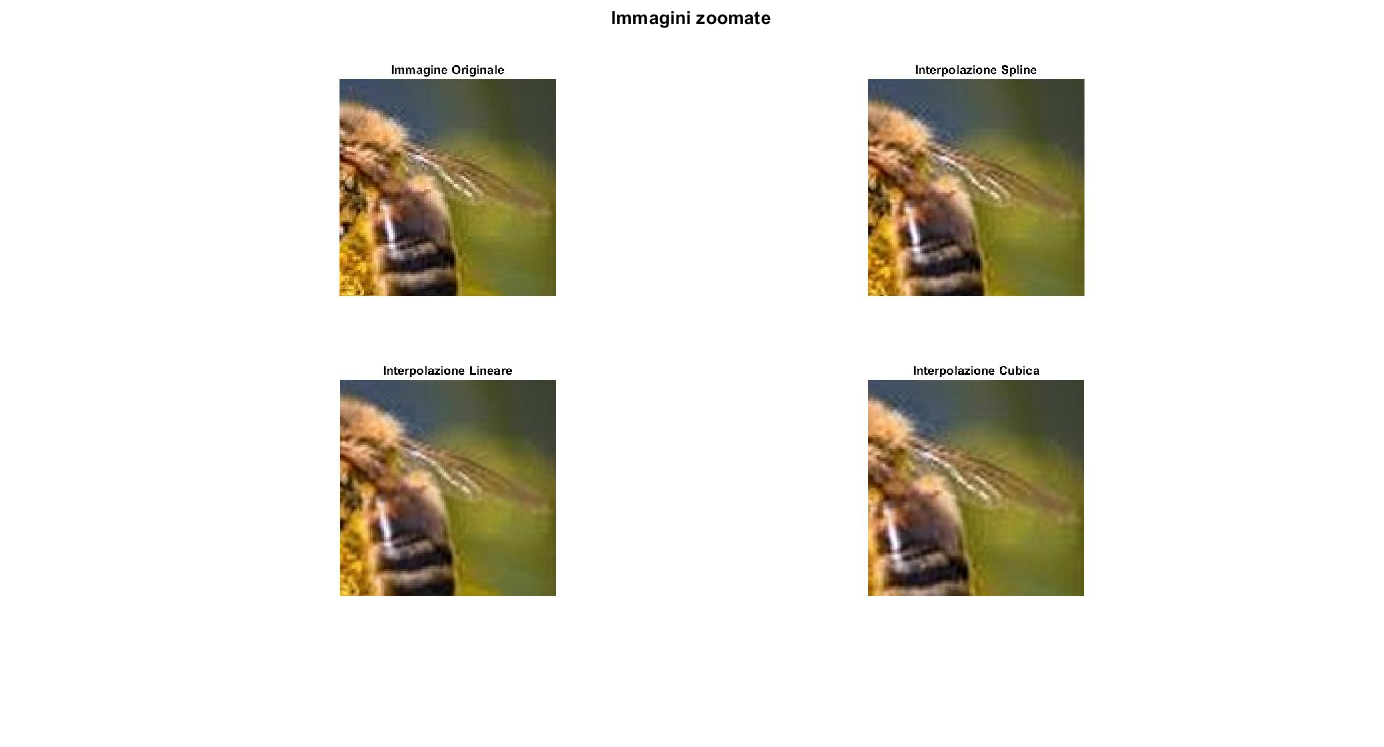

I2=imread('zoom.jpg');
figure(23),imshow(I2),title('Immagini zoomate');